# SEE data-driven NCC

## Read all .txt files in the folder

dinfo = dir('*.txt');
names_cell = {dinfo.name}';
names_Str = convertCharsToStrings(names_cell)

names_Str = 4×1 string array
    "1a_AuNpsNIE.txt"
    "1b_AuNpsBlank.txt"
    "2a_CatalaseNIE.txt"
    "2b_CatalaseBlank.txt"


## Import data by input the files' name

thisSignalAnalysis = SignalAnalysis(Filename)

Input -- **Filename** as a string, by defalut, consider there are other text string in the data file

Output -- **Sig.test_signal** Original signal vector in original unit

                **Sig.Test_time** Original time vector in original unit by default think it's in second 

                **Sig.Test_freq** test frequency depends on the test_time vector by default it's Hz

    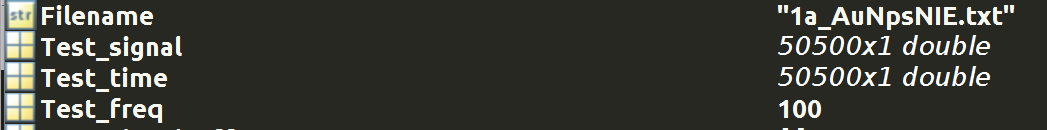

Sig1 = SignalAnalysis(names_Str(1));
Sig2 = SignalAnalysis(names_Str(3));
Back1 = SignalAnalysis(names_Str(2));
Back2 = SignalAnalysis(names_Str(4));

## Preprocess

[theSignalAnalysis] = Preprocess(theSignalAnalysis,OriginalUnit,Timeshift,Resample,ResamplePlot)

Input -- 

**OriginalUnit** a string of orgiginal data's unit e.g. 'pA', it will convert different current into pA in this toolbox 

**Timeshift** whether or not performing the time shift, will shift the test_time starts from 0 input string as e.g. 'y'

**Resample** whether or not to perform the resampling for uneven sampling, input string as e.g. 'y'

**ResamplePlot** whether or not to show the plot with and without resampling , input string as e.g. 'y'

Output -- 

**Sig.test_signal** converted unit signal vector, depending on chosen option becomes resampled signal 

**Sig.Test_time** updated time vector in original unit, depending on chosen option becomes shifted time from 0

**Sig.Test_freq **updatedtest frequency depends on the test_time vector

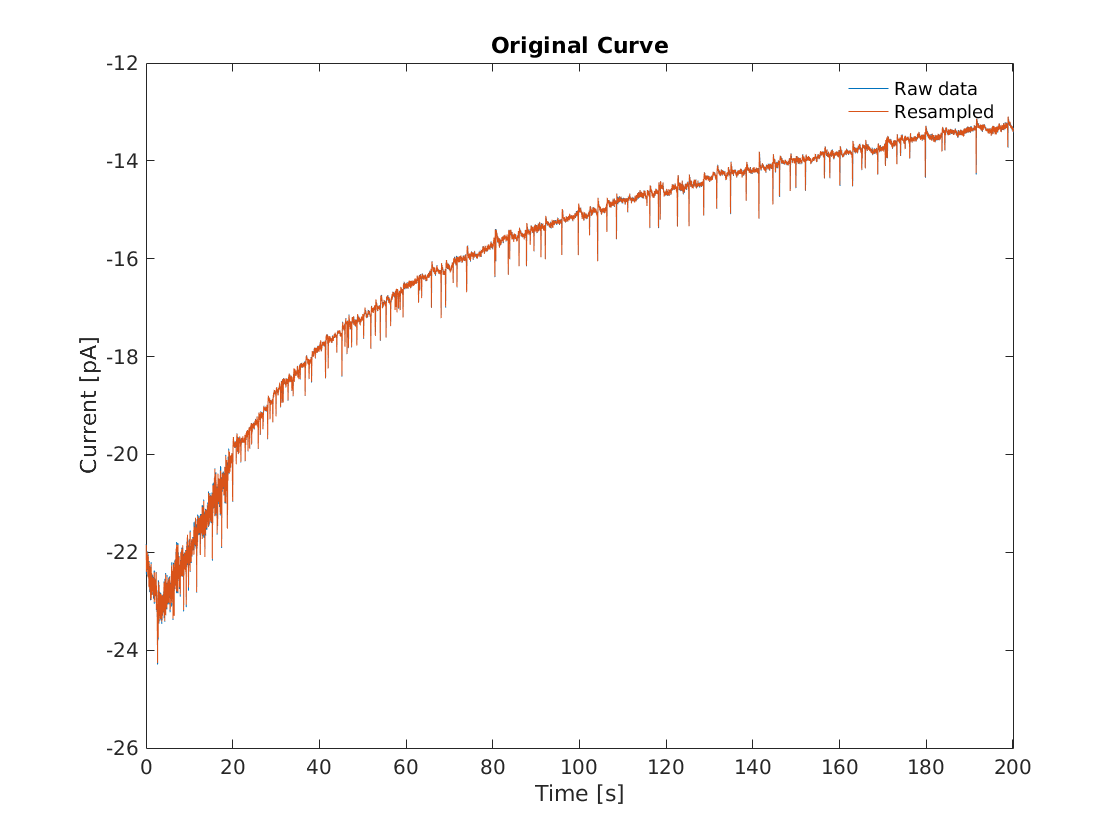

Sig1 = Sig1.Preprocess("A","Y","N","N");
Back1 = Back1.Preprocess("A","Y","N","N");
Sig2 = Sig2.Preprocess("PA","N","Y","Y");

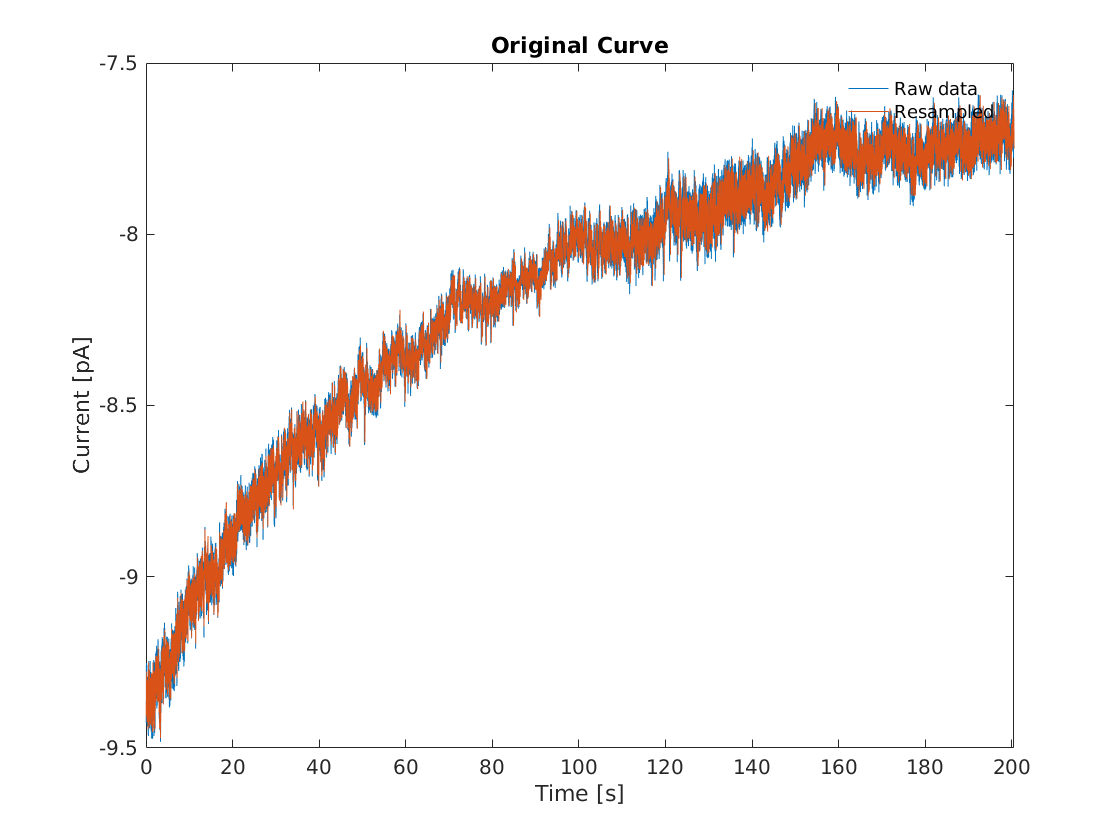

Back2 = Back2.Preprocess("PA","N","Y","Y");

## Denoise

Removing the undesired electrical noise

[theSignalAnalysis] = Denoise(theSignalAnalysis,CutoffFreq,FilterOrder)

Input --  

**CutoffFreq** the cut-off frequency to apply for FIR filter, the spike frequency can get from stft plot by leaving CutoffFreq empty, suggest running in .m since the in .mlx the plot won't show instantly e.g. 10

**FilterOrder **the order for the FIR filter also known as term number,  higher the order, shaper the filter at pass band, but higher the delay, we din't perform the zero-phase filtering in this toolbox e.g. 10, can be changed in the command window it will ask wether or not to change, if enter no or nothing it won't change 

Output -- 

**Sig.test_signal** Denoised signal

**Sig.Test_time **After denoising the time vector may shift due to the convolution, the filter length of data get abandoned (normally less than 20)

Denoise can either leave frequency it will output the stft plot and set frequency by inputing in the command window

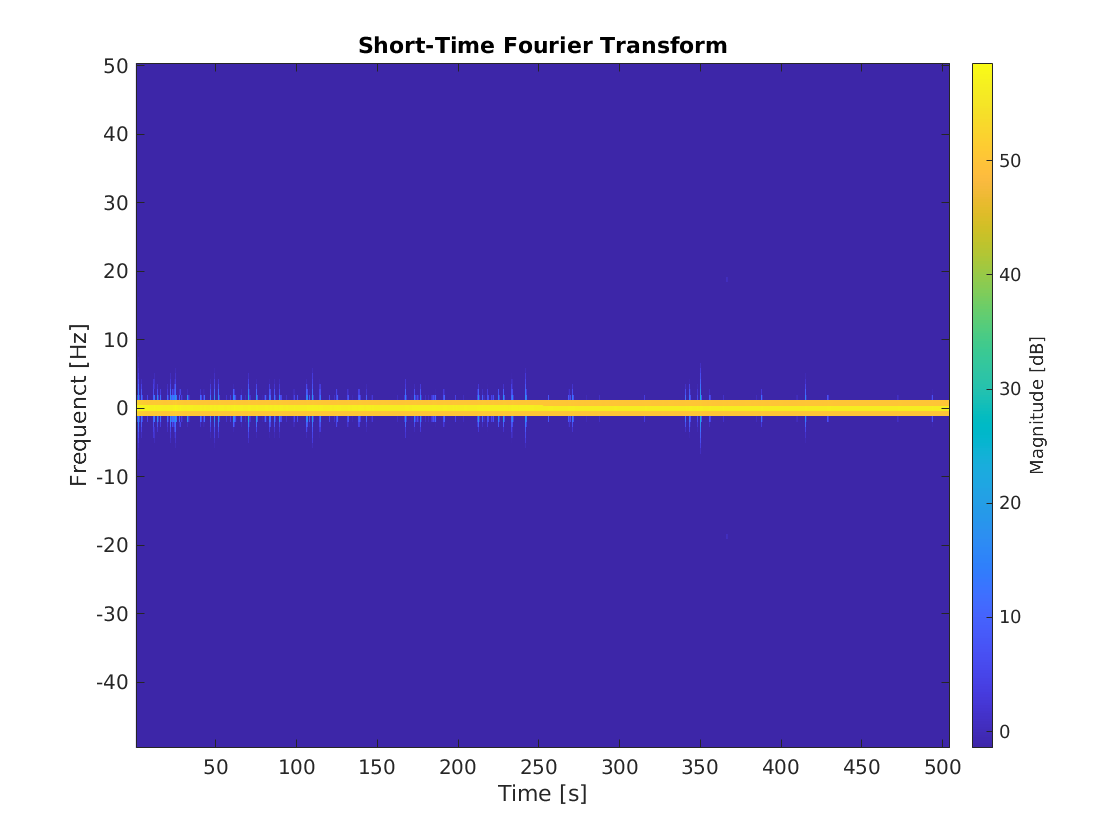

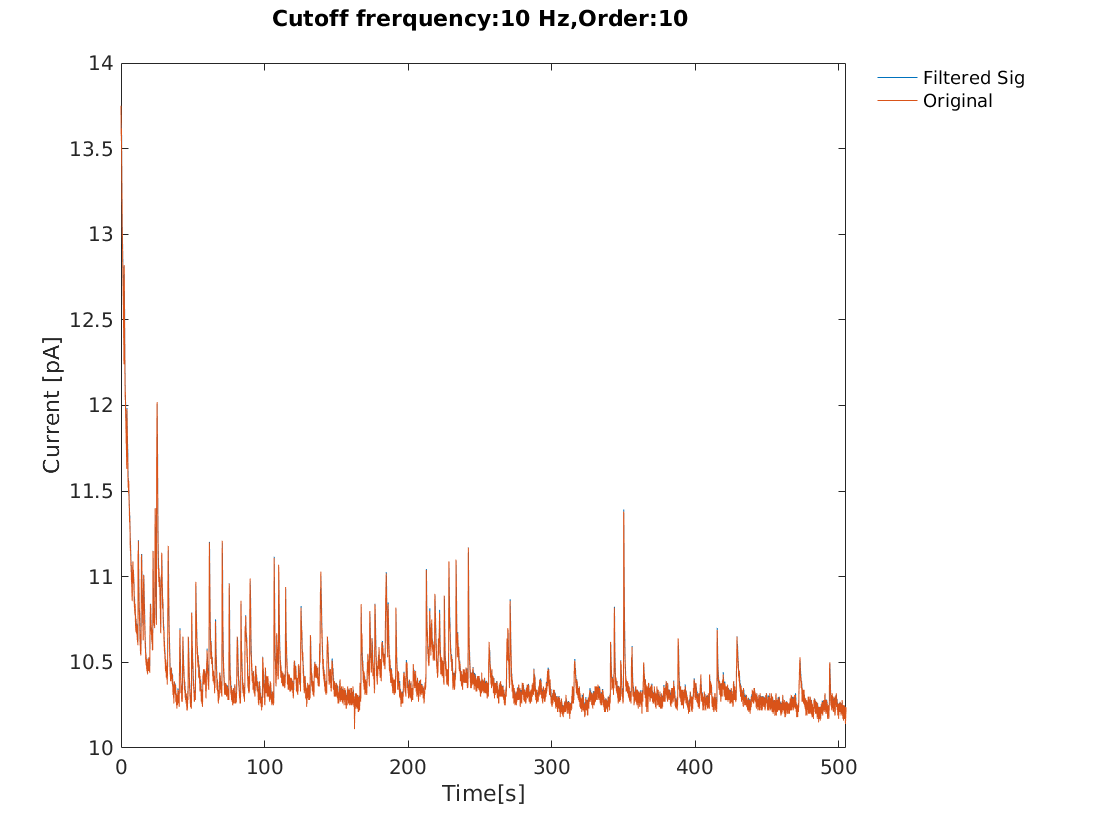

Sig1 = Sig1.Denoise([],10);

Or directly input the cut-off frequency

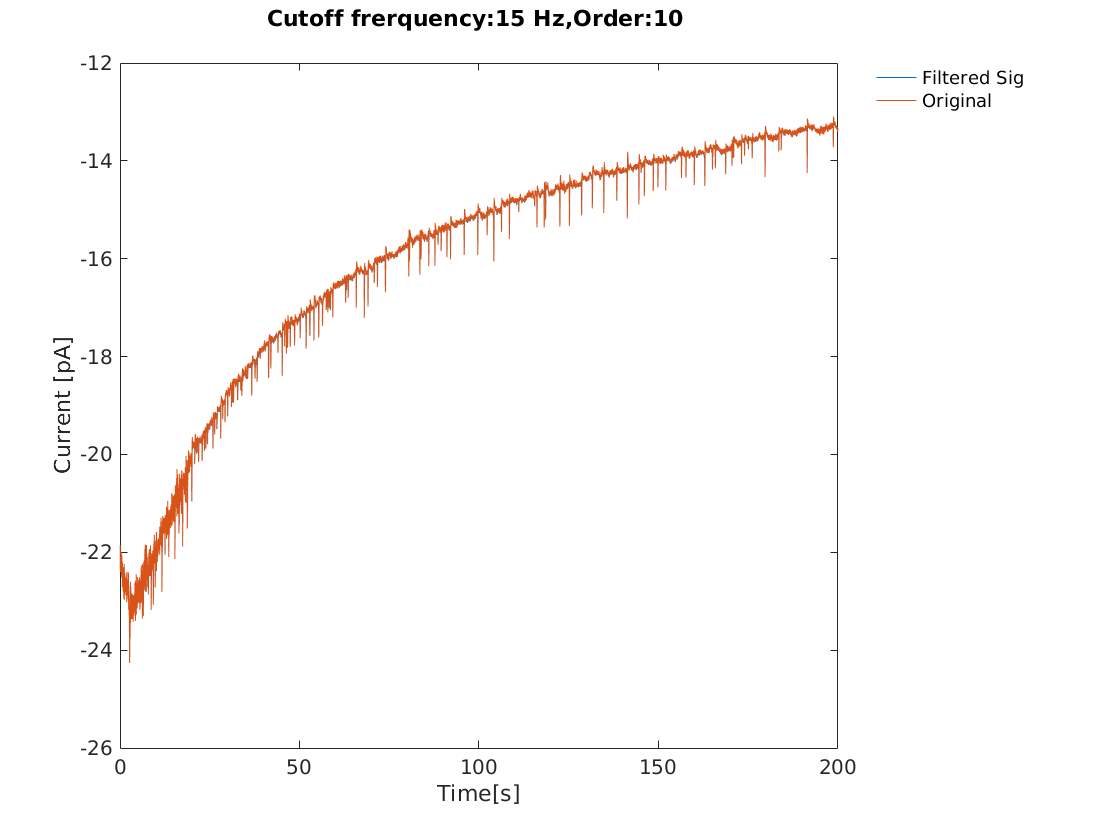

Sig2 = Sig2.Denoise(15,10);

## BackgroundSubtraction 

Correct baseline into 0 baseline

[theSignalAnalysis] = BgSub(theSignalAnalysis,WinSize,Plotstates)

Input -- 

**WinSize** Windows size, by default set as 1000, lower the value, and the curve fits better the NIE spikes(undesired).

**Plotstates** whether or not showing the plot for the background subtraction, Output a subplot the first is the test_signal with a fitted trend line. The second one is the offset signal

Output--

**Sig.test_signal_offset **Offset signal data vector

**Sig.test_signal_trendline **Fitted trendline 

#### Fitted trend line for AuNp Sig1

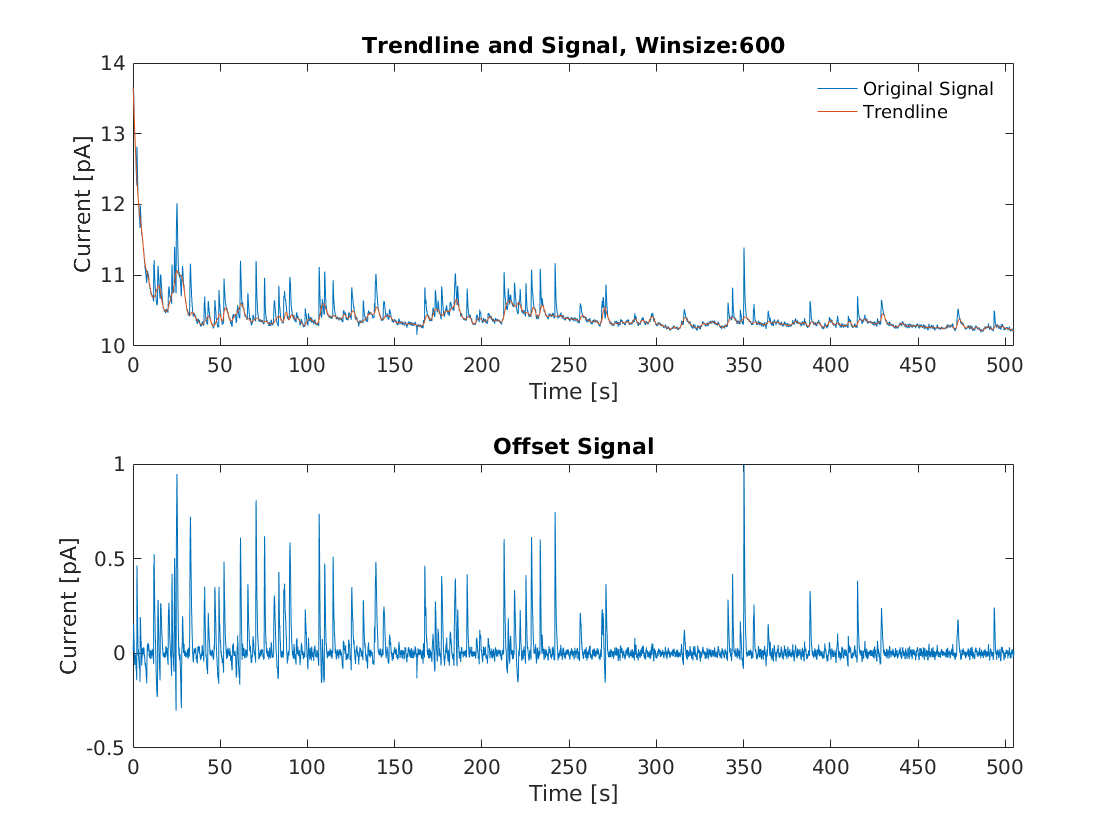

Winsize = 600;
Sig1 = Sig1.BgSub(Winsize,'y');

Back1 = Back1.BgSub(1000,'N');

#### Fitted trend line for Catalase Sig2

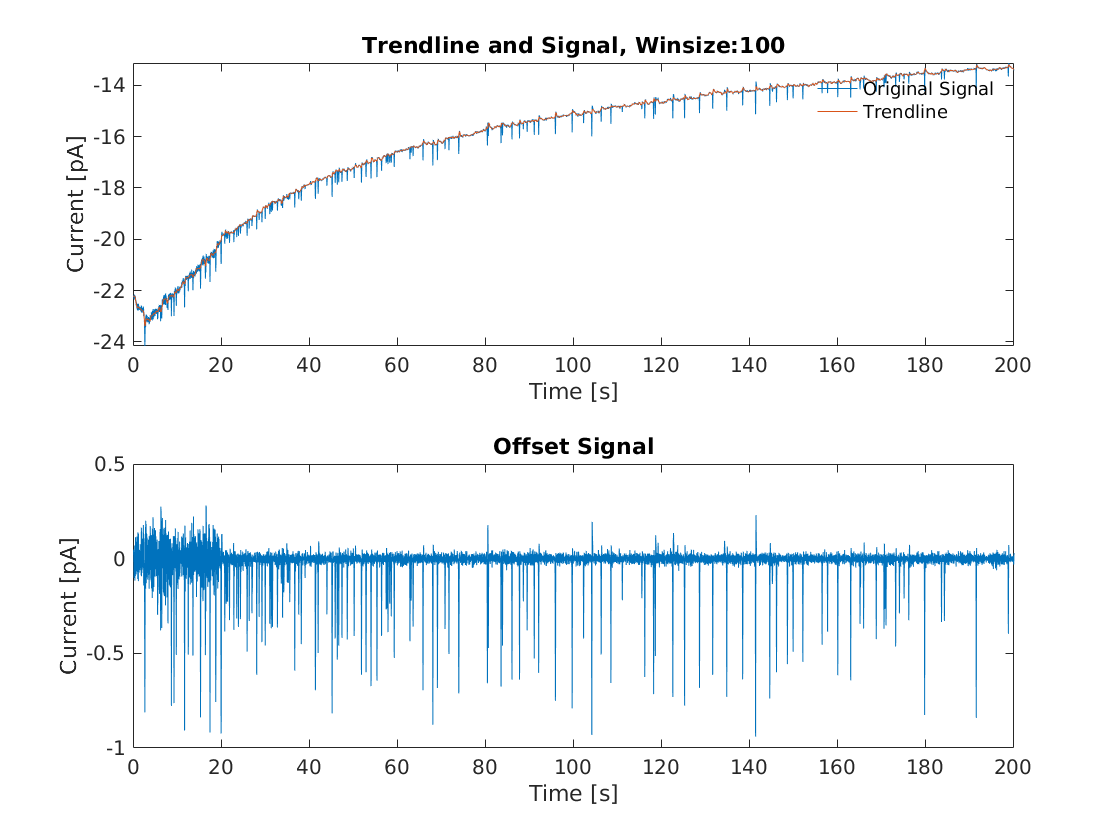

Winsize = 100;
Sig2 = Sig2.BgSub(Winsize,'y');

Back2 = Back2.BgSub(1000,'N');

## Sampling peaks by height threshold based on blank

 [theSignalAnalysis] = FlipFindPeak(theSignalAnalysis,BackgroundSigOffset,ReactionStates,Plotstates,PlotIndex)

Input --

BackgroundSigOffset 

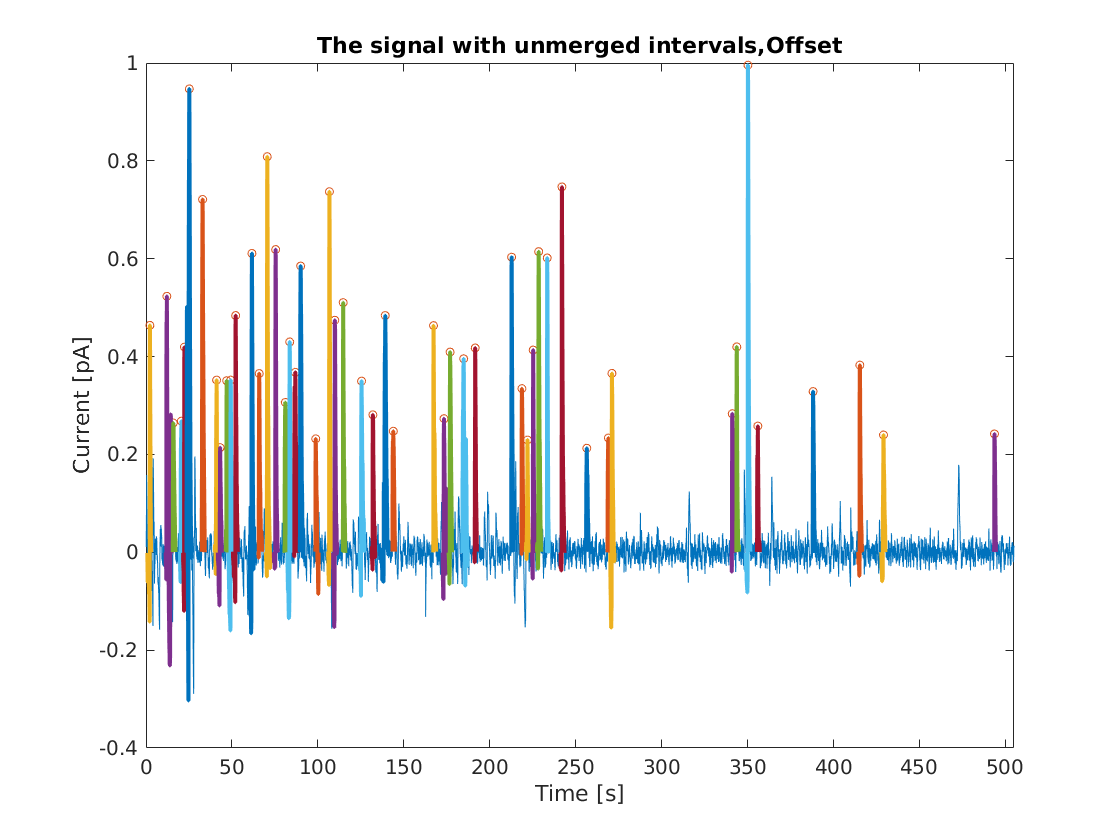

Sig1 = Sig1.FlipFindPeak(Back1.Test_signal_offset,'Oxi','Y',"Offset");

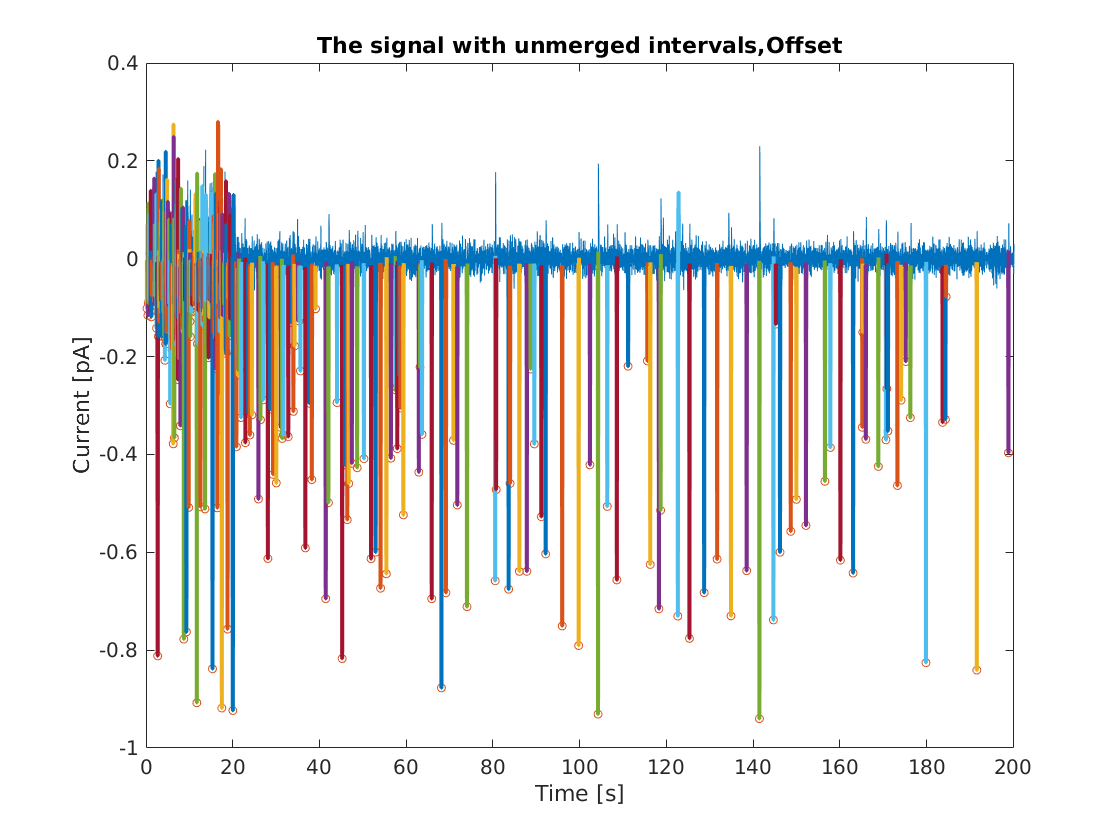

Sig2 = Sig2.FlipFindPeak(Back2.Test_signal_offset,'Red','Y',"Offset");

## TraningSet generation

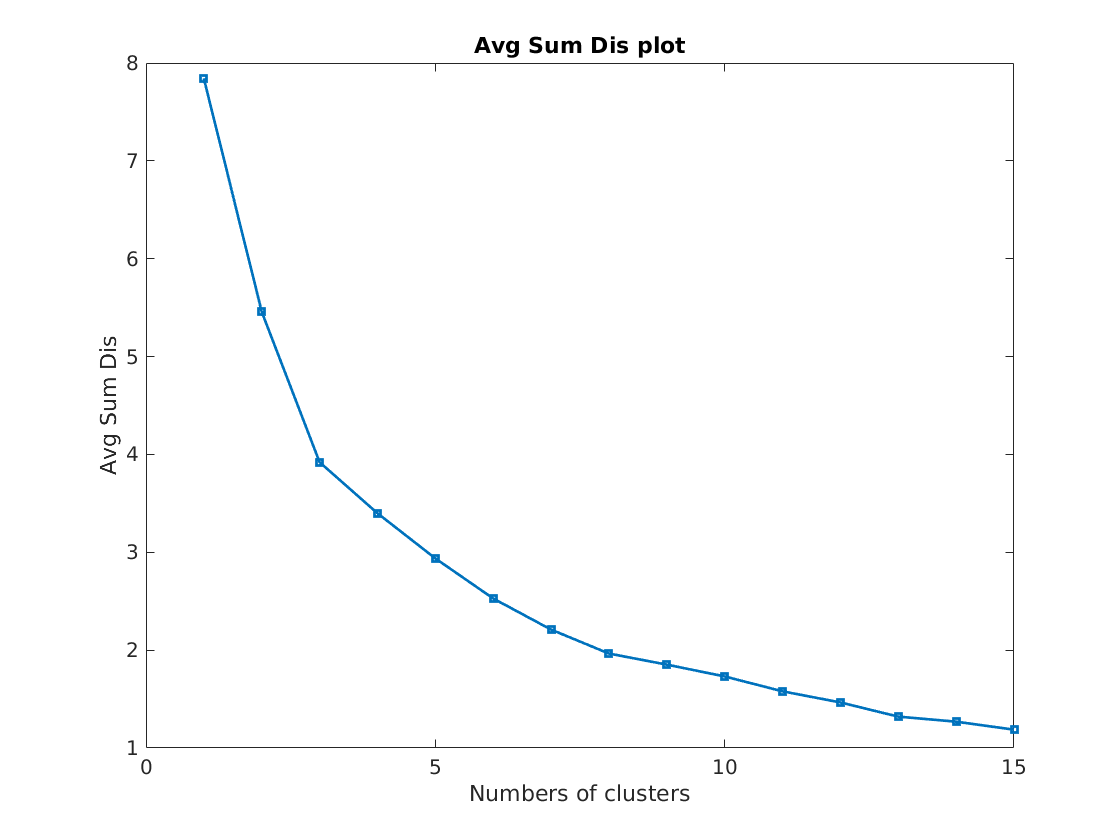

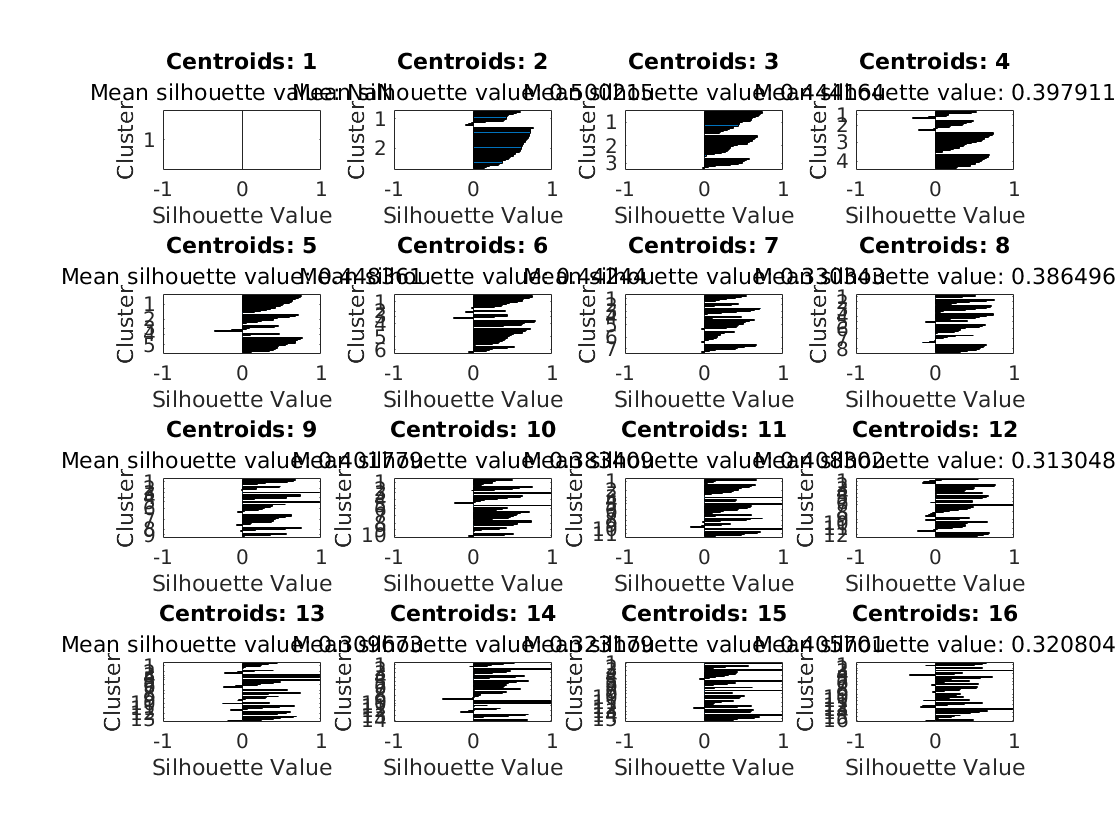

Sig1 = Sig1.GeRawTrainSet('Y','Y');

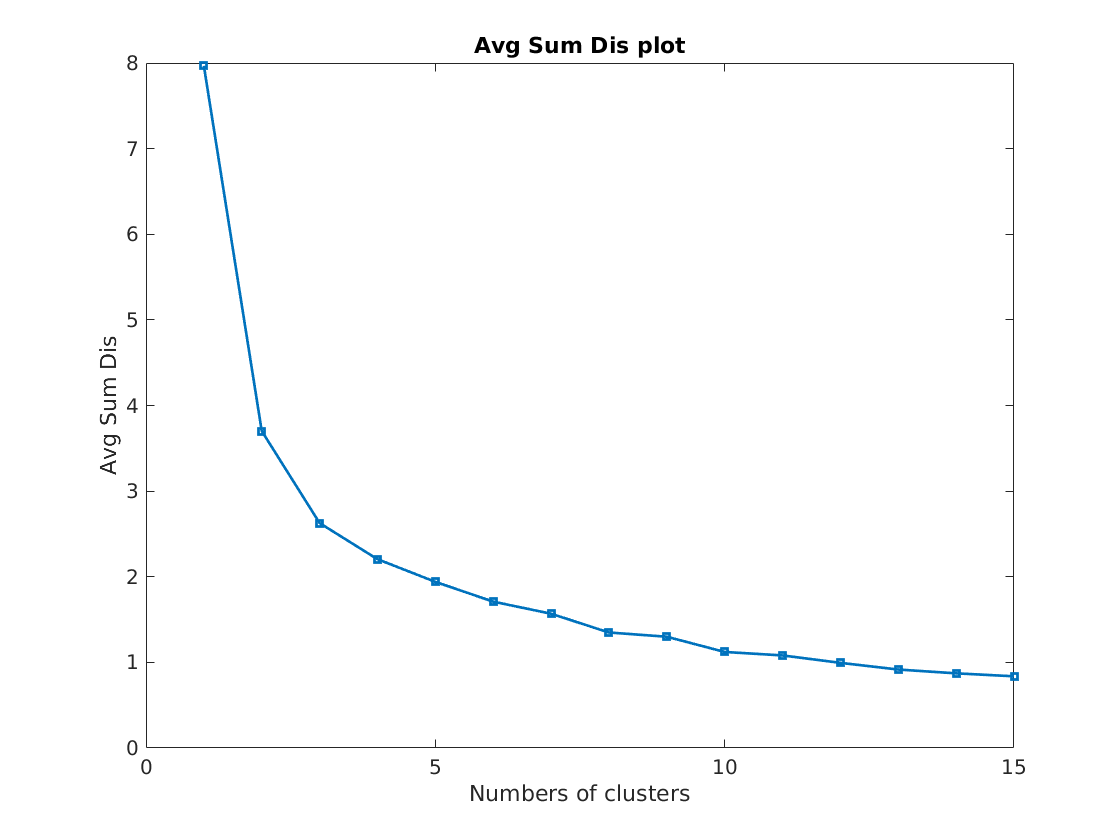

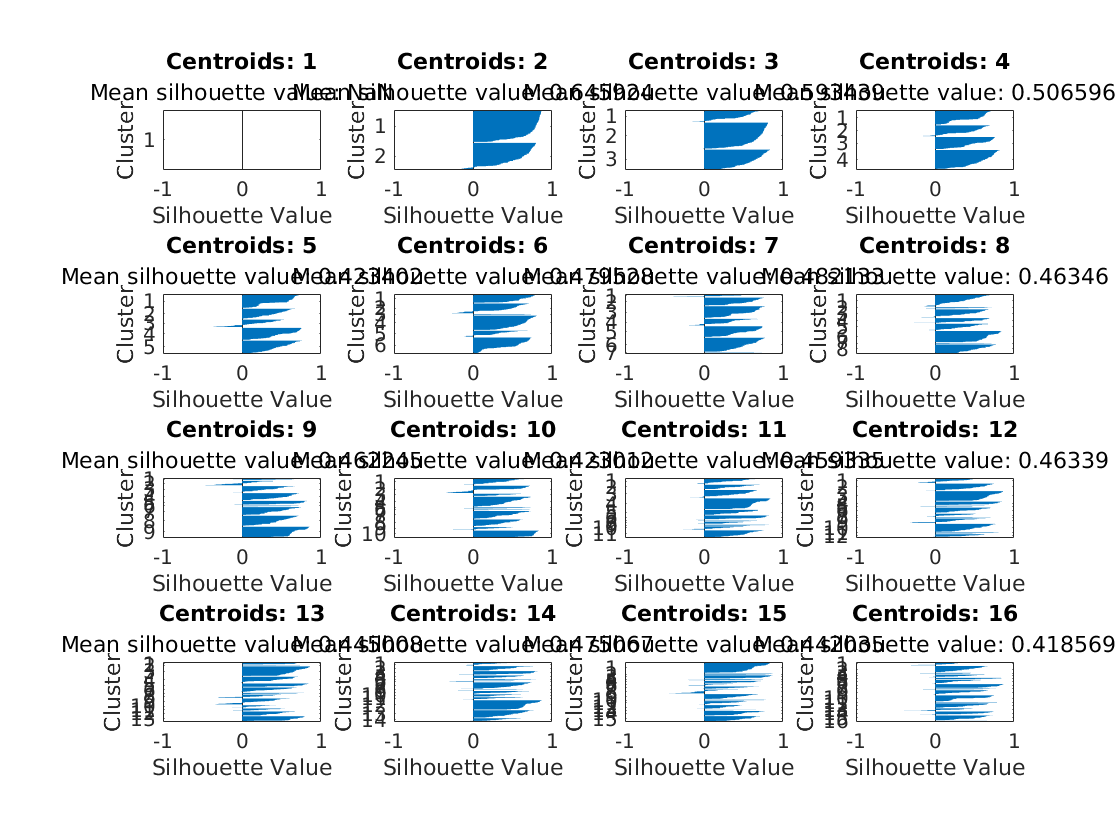

Sig2 = Sig2.GeRawTrainSet('Y','Y');

## Clustering and Raw unregularated templates generation

Starting parallel pool (parpool) using the 'local' profile ...
Connected to the parallel pool (number of workers: 12).


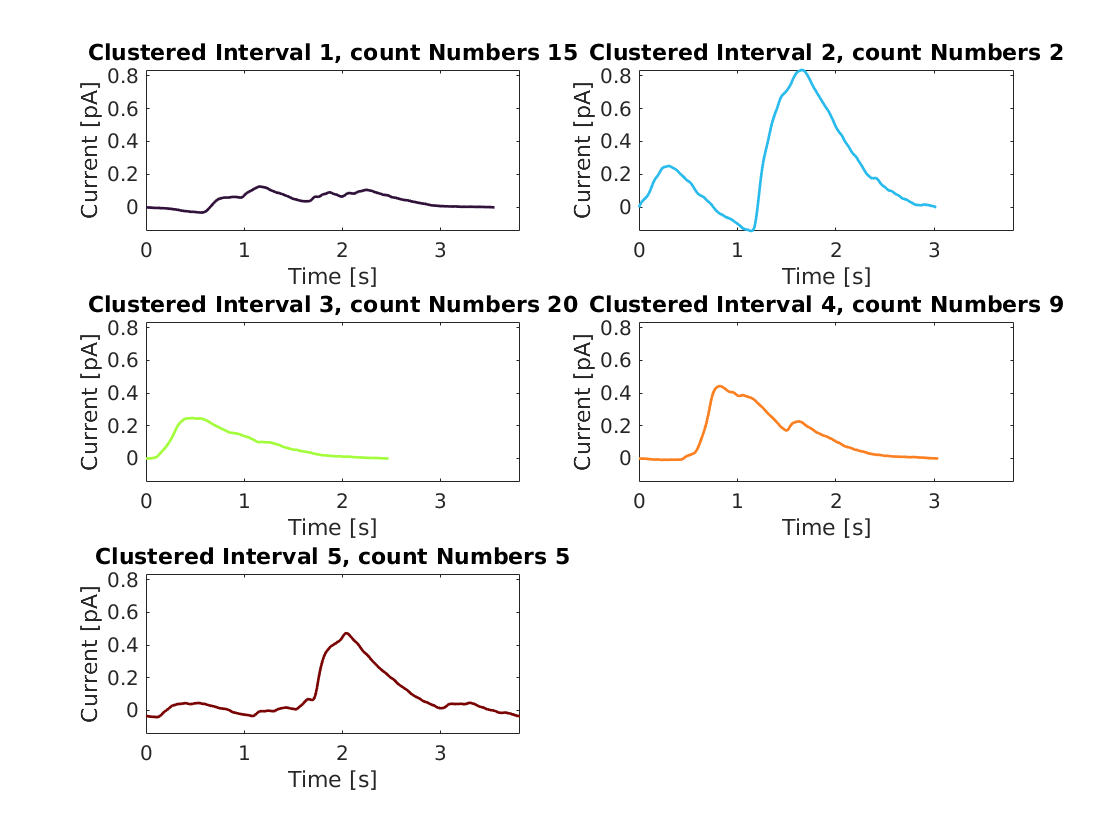

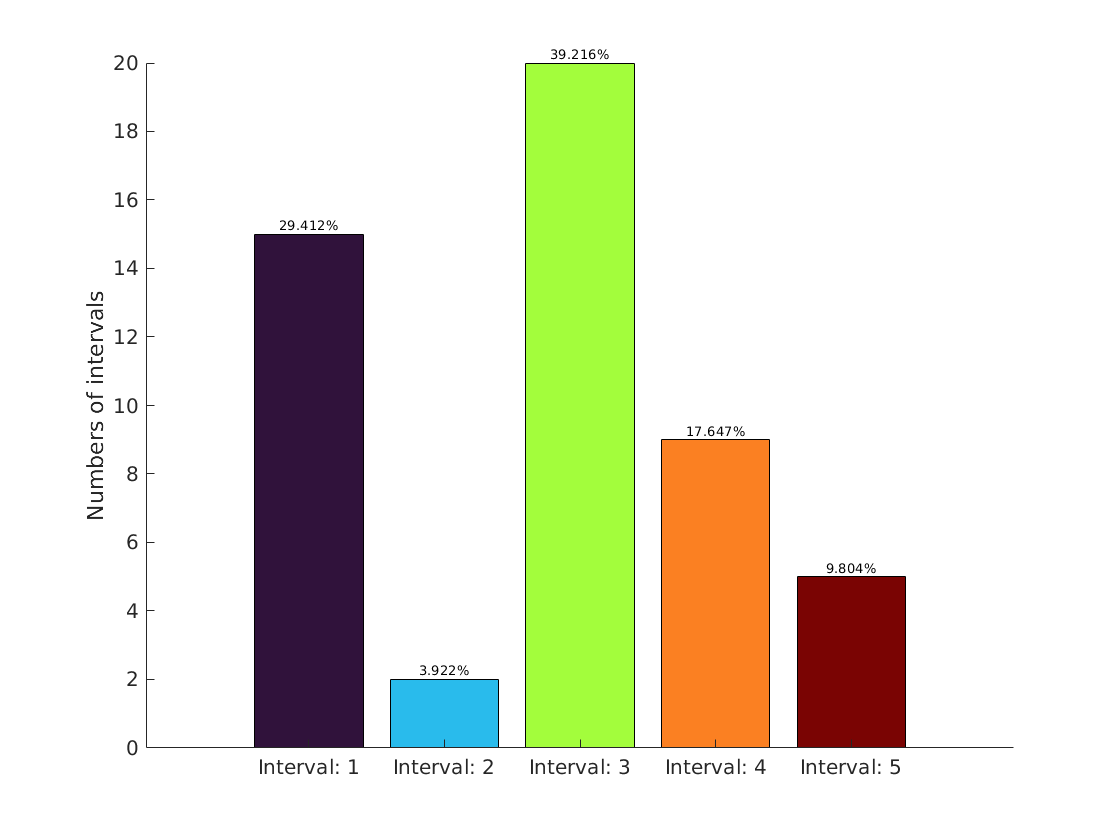

Sig1 = Sig1.KmeansGeRawSigTem(5,'Y',"Y");

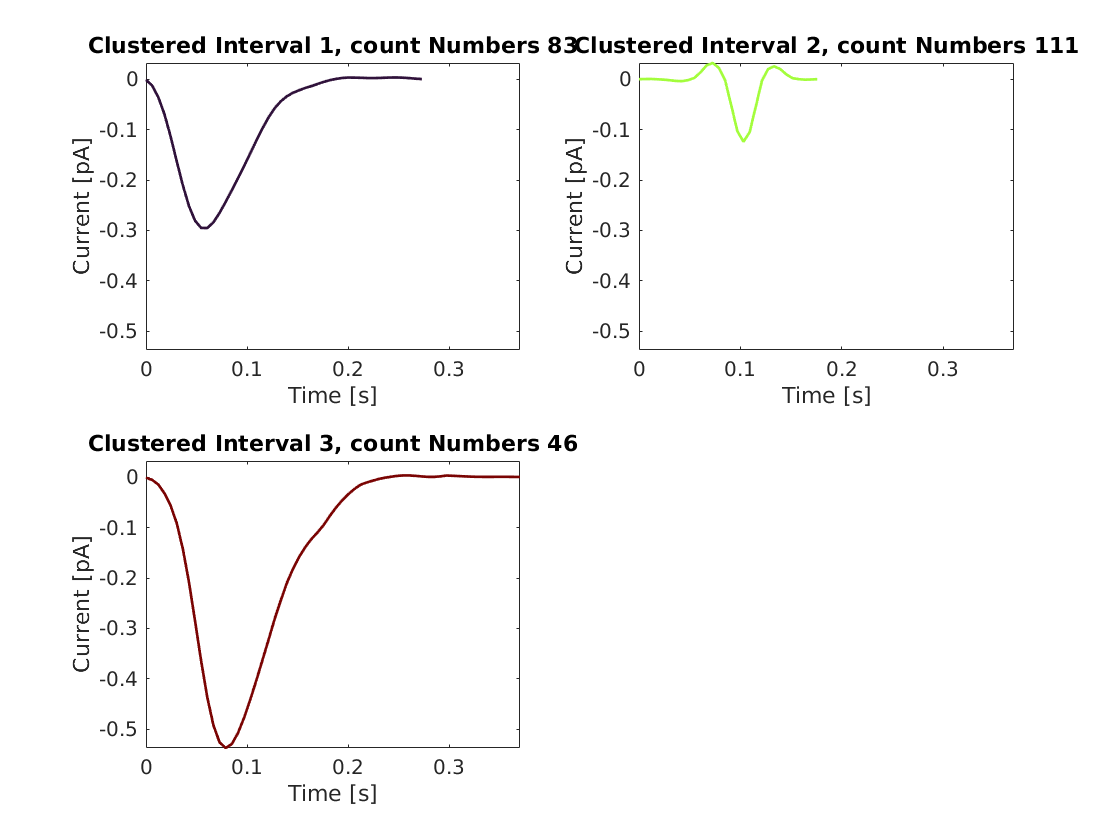

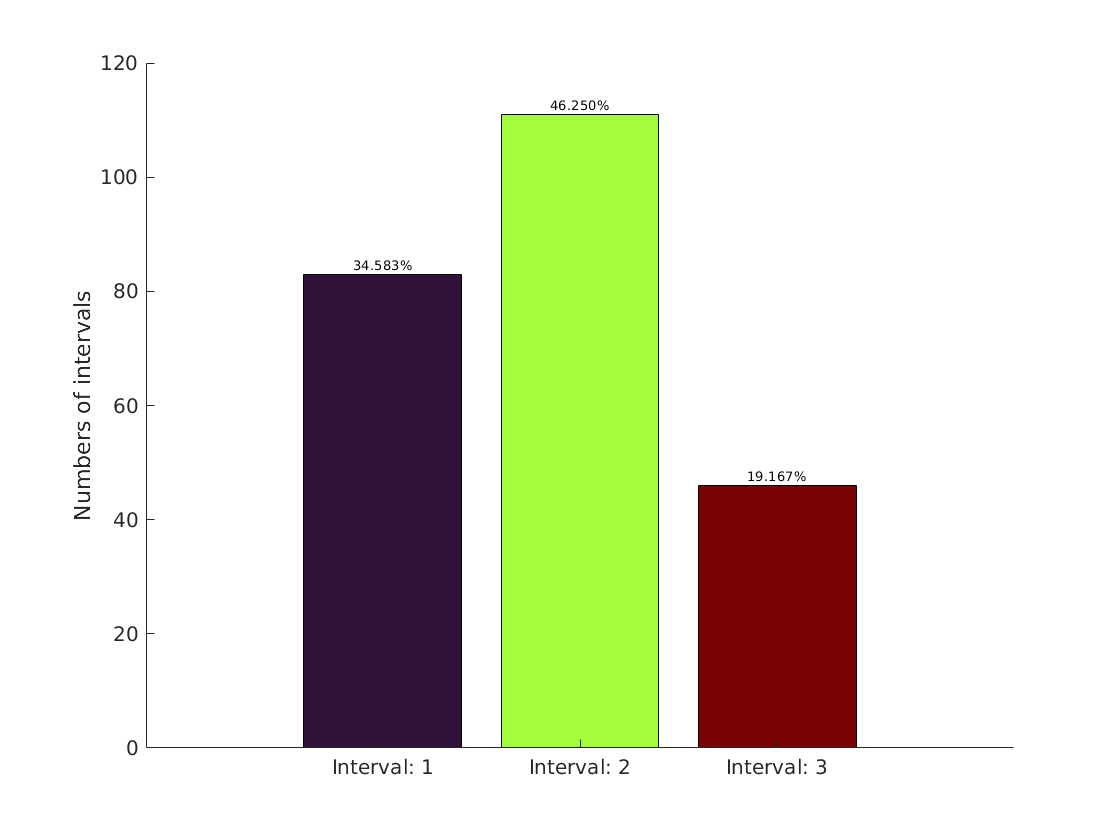

Sig2 = Sig2.KmeansGeRawSigTem(3,'Y',"Y");

## Regulated Templates

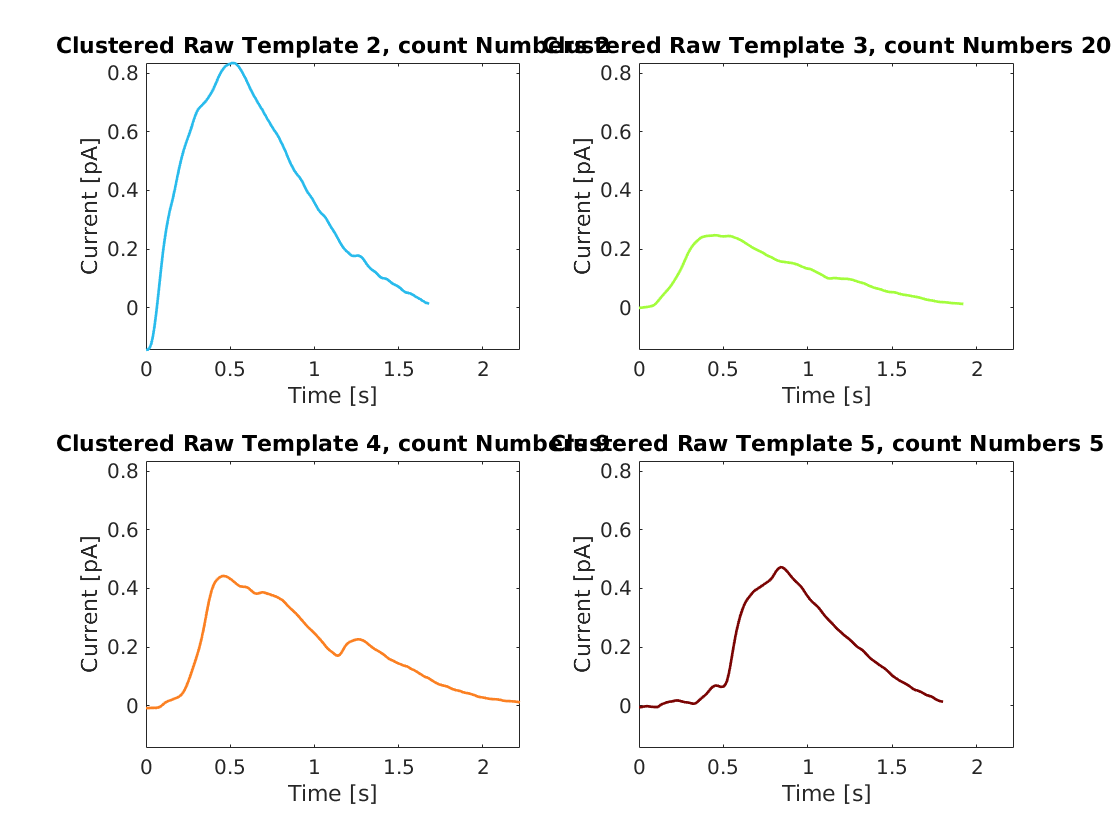

Sig1 = Sig1.RawtemplatesReguFunc([2,3,4,5],'Y');

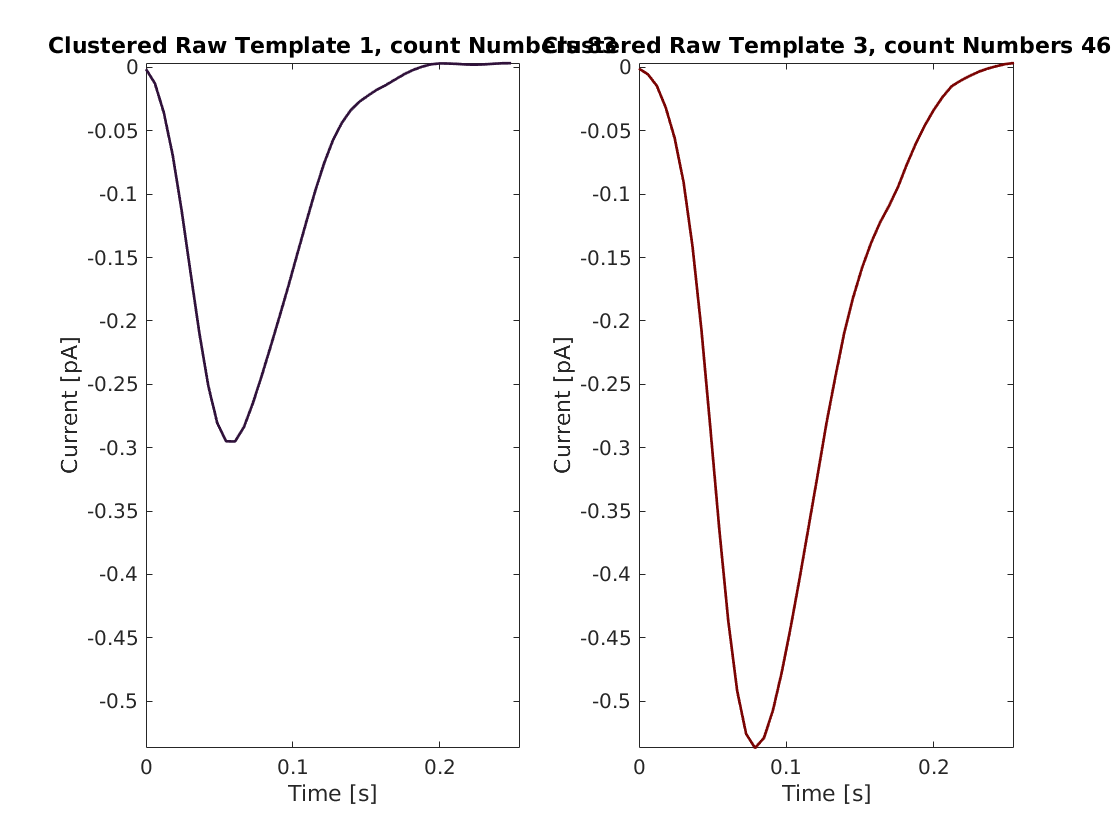

Sig2 = Sig2.RawtemplatesReguFunc([1,3],'Y');

## Template Matching

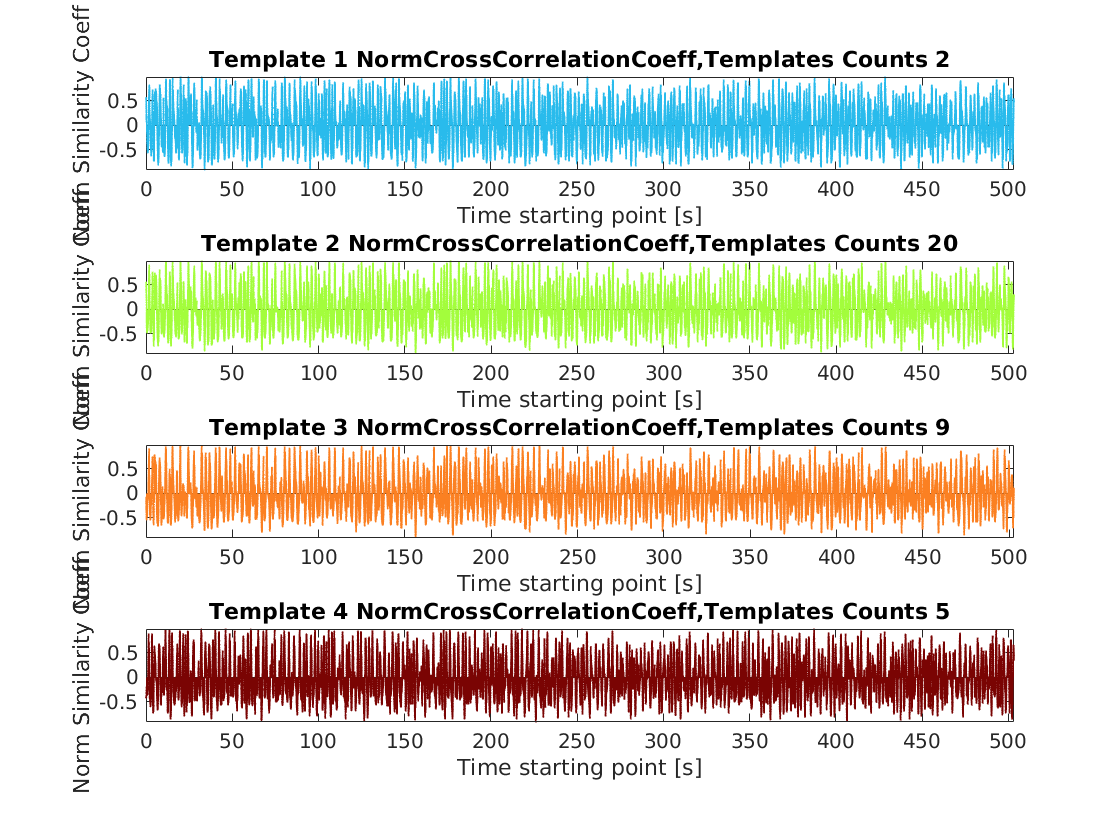

Sig1 = Sig1.Templatematching('Y');

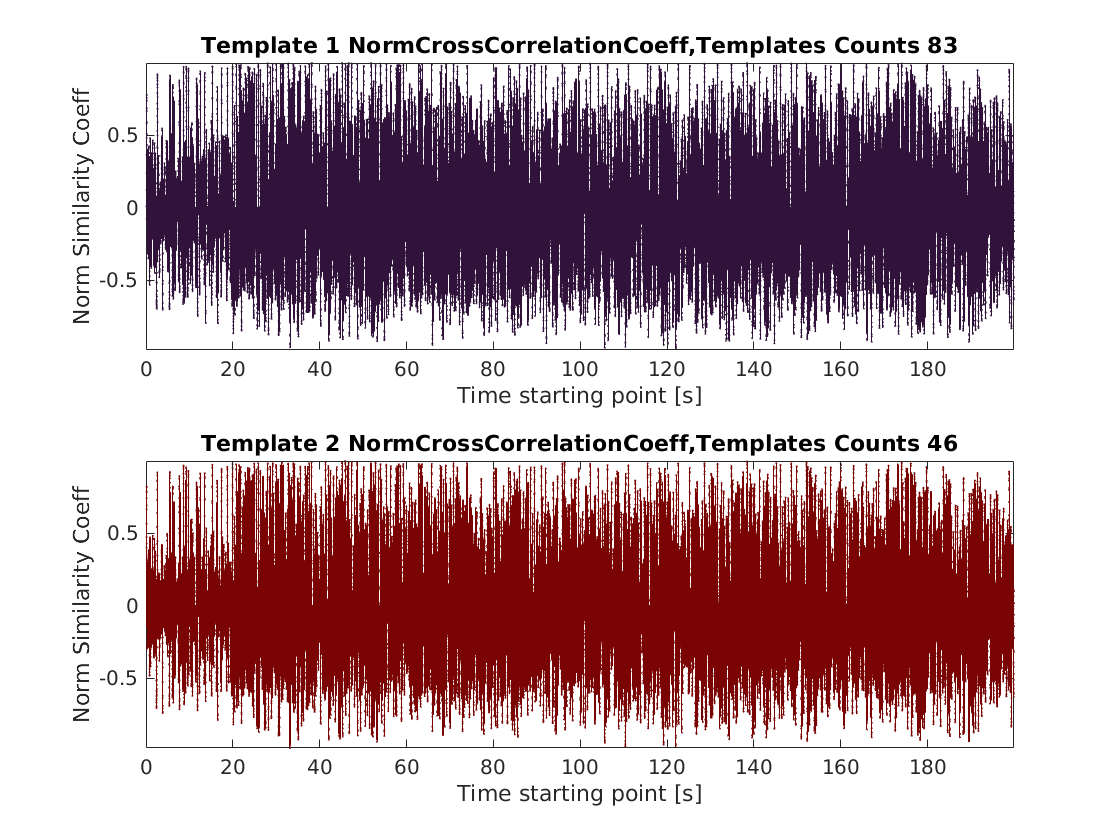

Sig2 = Sig2.Templatematching('Y');

## Template filtered the peaks Sig1

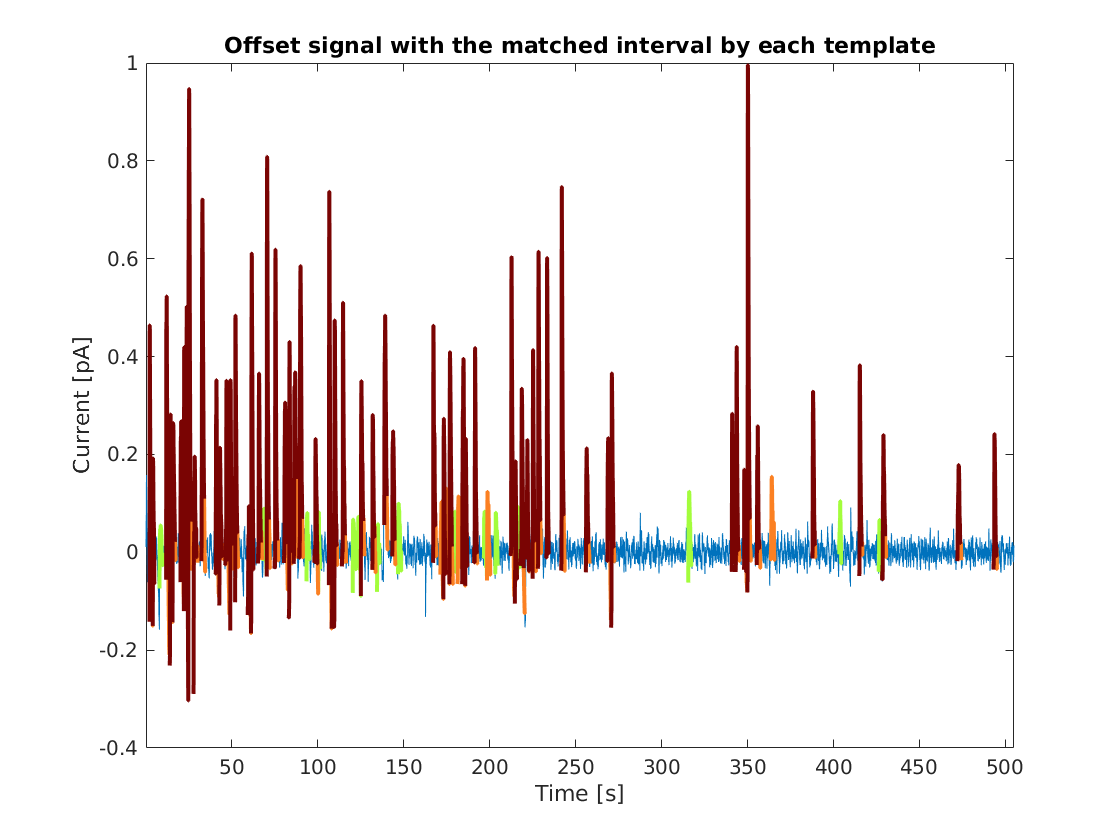

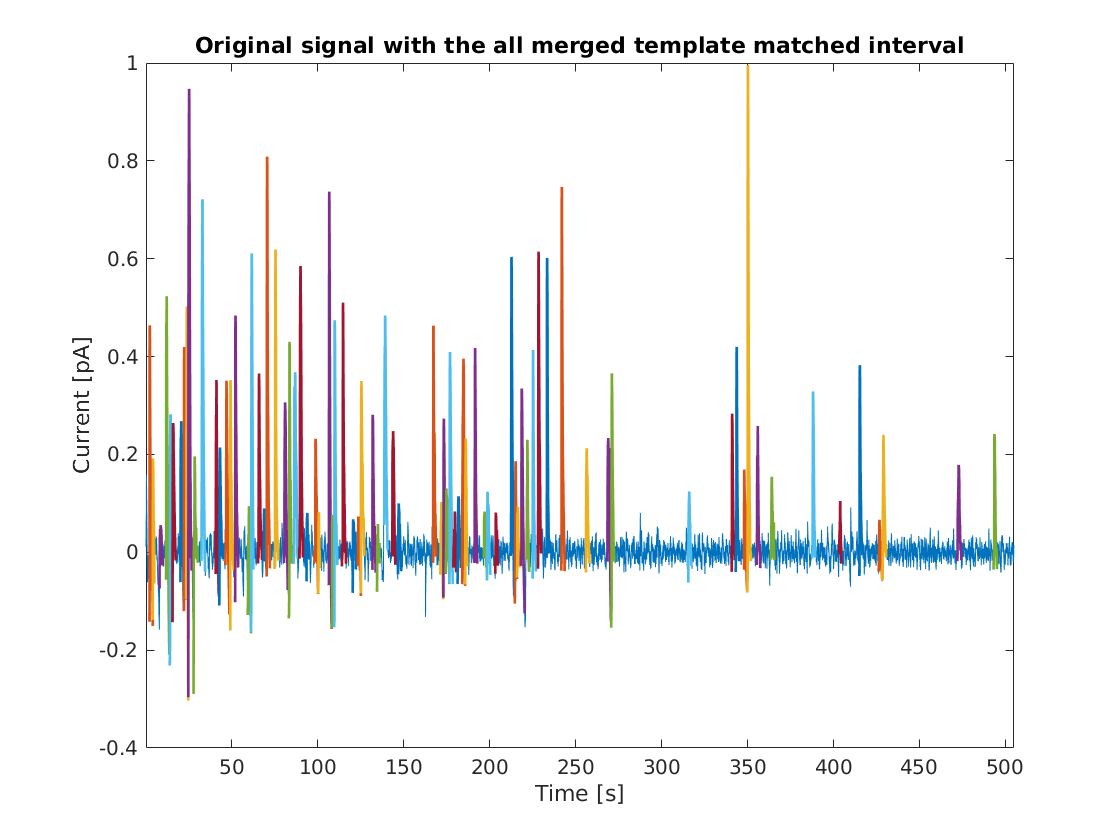

Sim = 0.9;
StdCoeff = 0.35;
HeightWidth = 0.35;
Sig1 = Sig1.TemplatematchingFiltering(Sim,StdCoeff,HeightWidth,'Y','Y');

## Template filtered the peaks Sig2

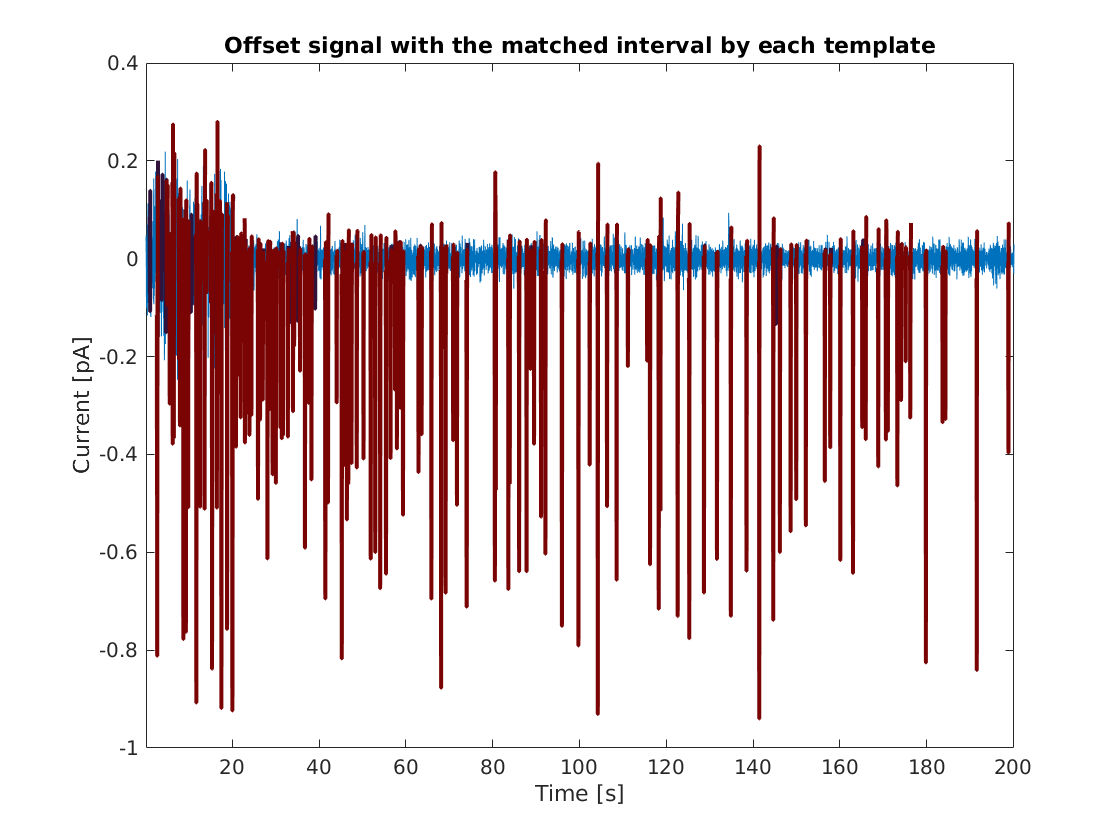

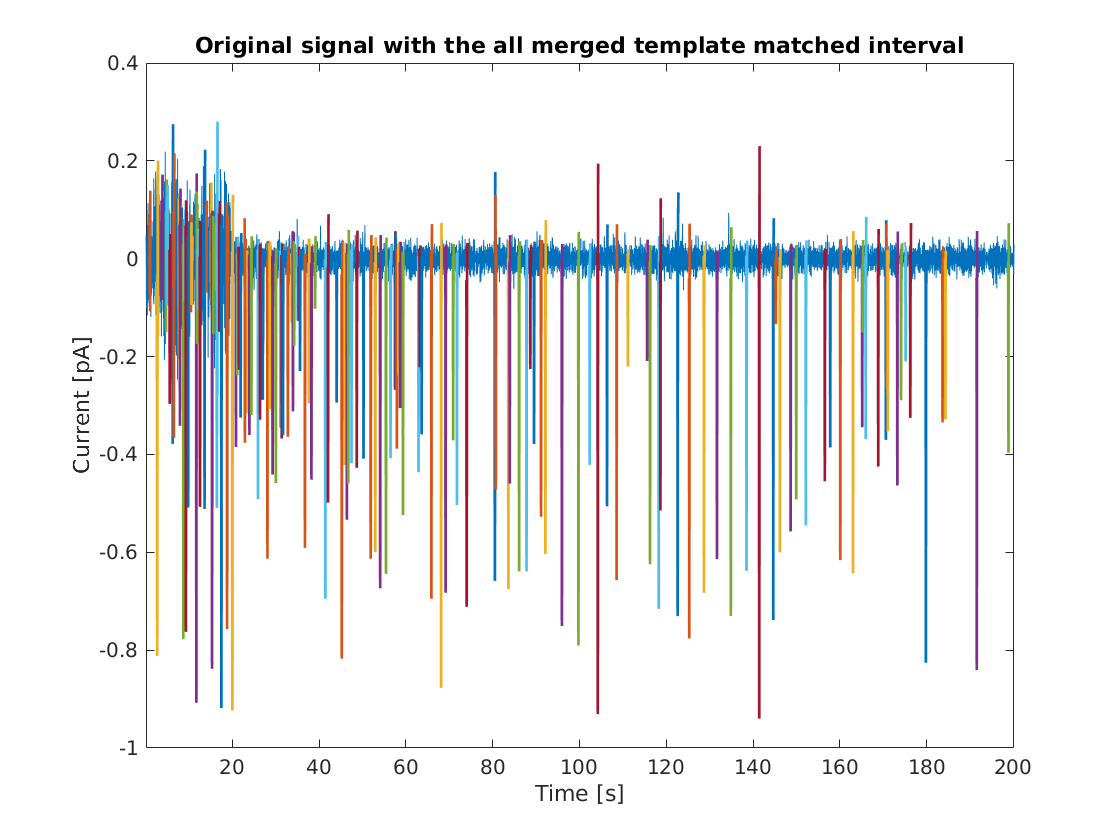

Sim = 0.9;
StdCoeff = 0.35;
HeightWidth = 0.35;
Sig2 = Sig2.TemplatematchingFiltering(Sim,StdCoeff,HeightWidth,'Y','Y');

## TraninignSet ReClustering

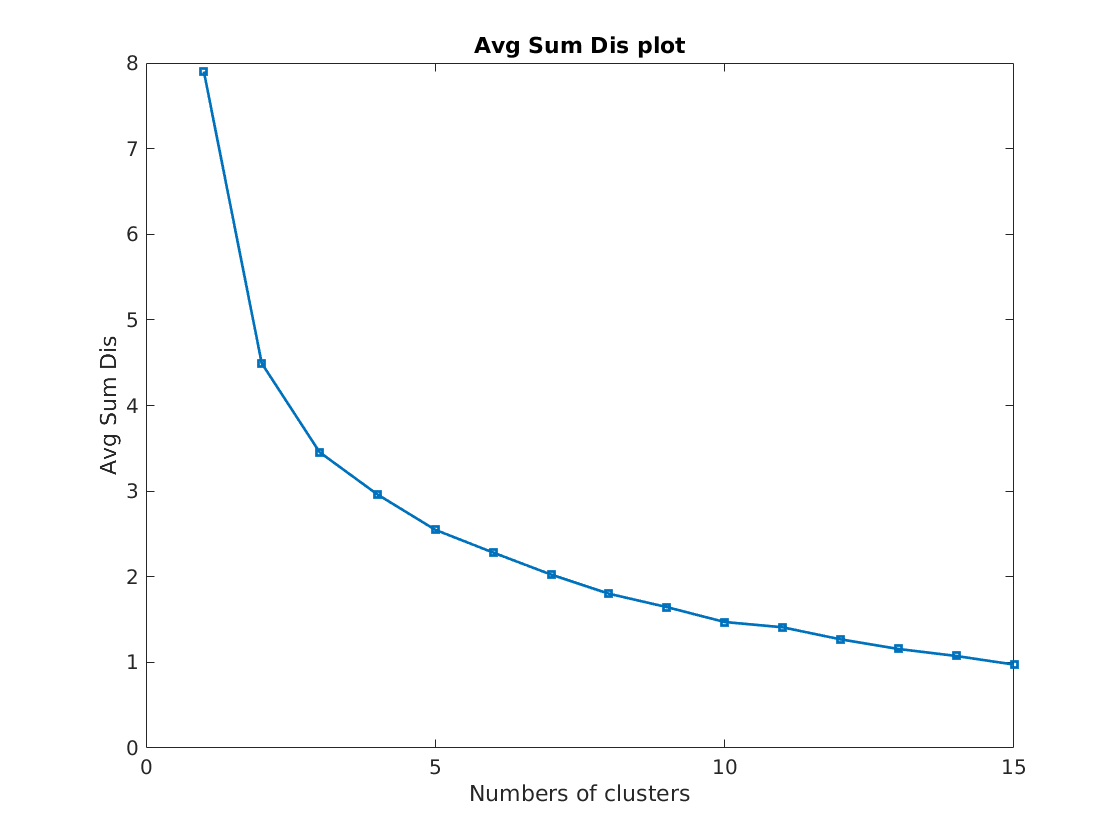

Sig1 = Sig1.GeAMTrainSet('N','Y',"N");

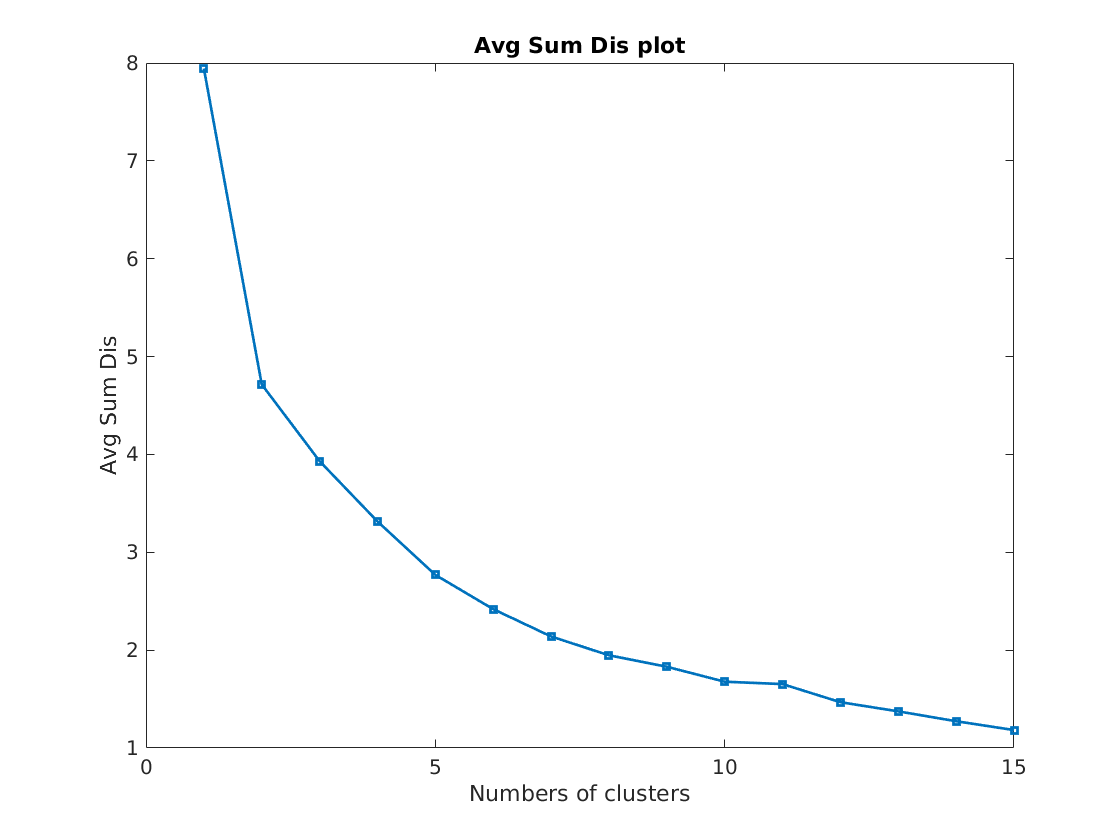

Sig2 = Sig2.GeAMTrainSet('Y','Y',"N");

## ReClustering and generate the templates

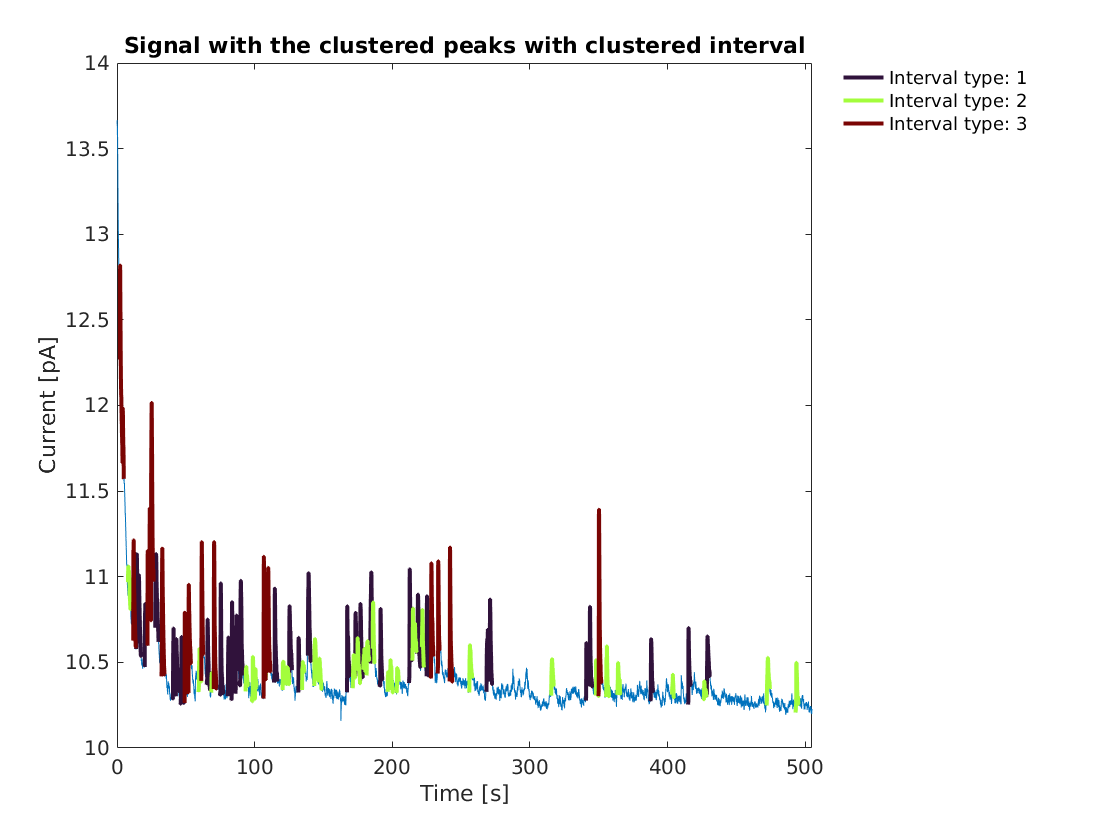

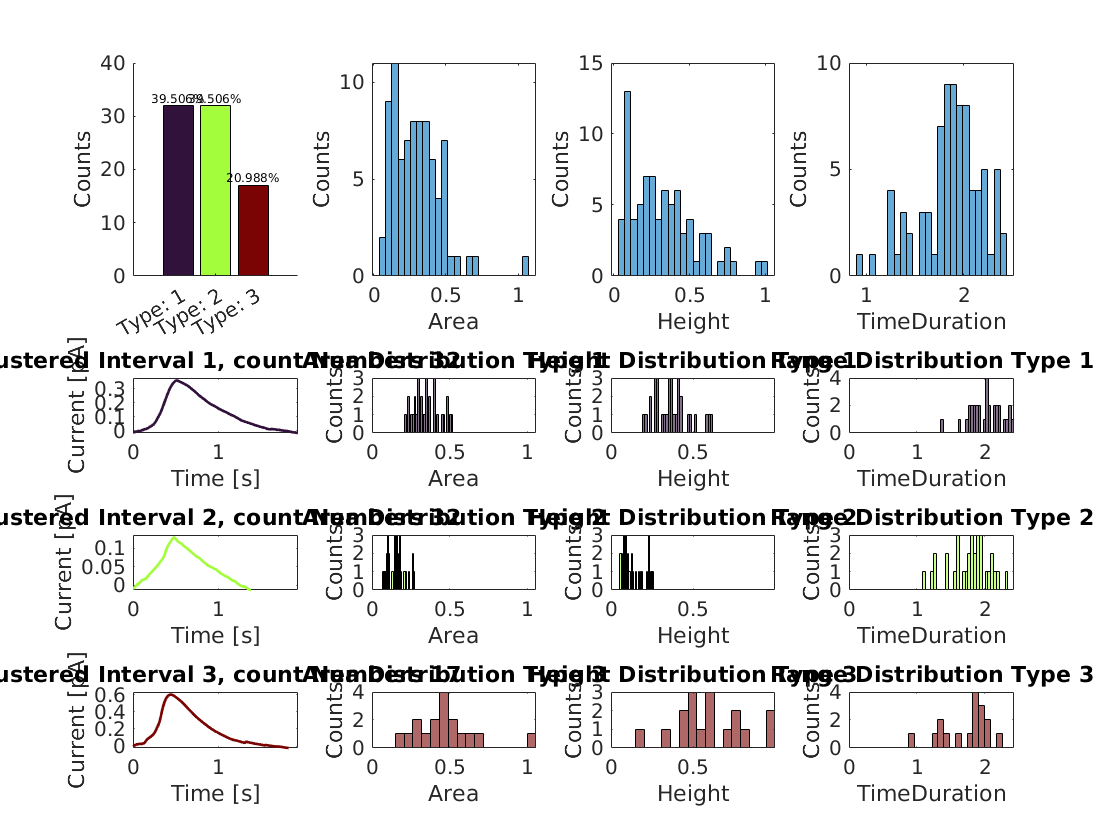

Sig1 = Sig1.KmeansGeAMSigTem(3,"Y","Y");

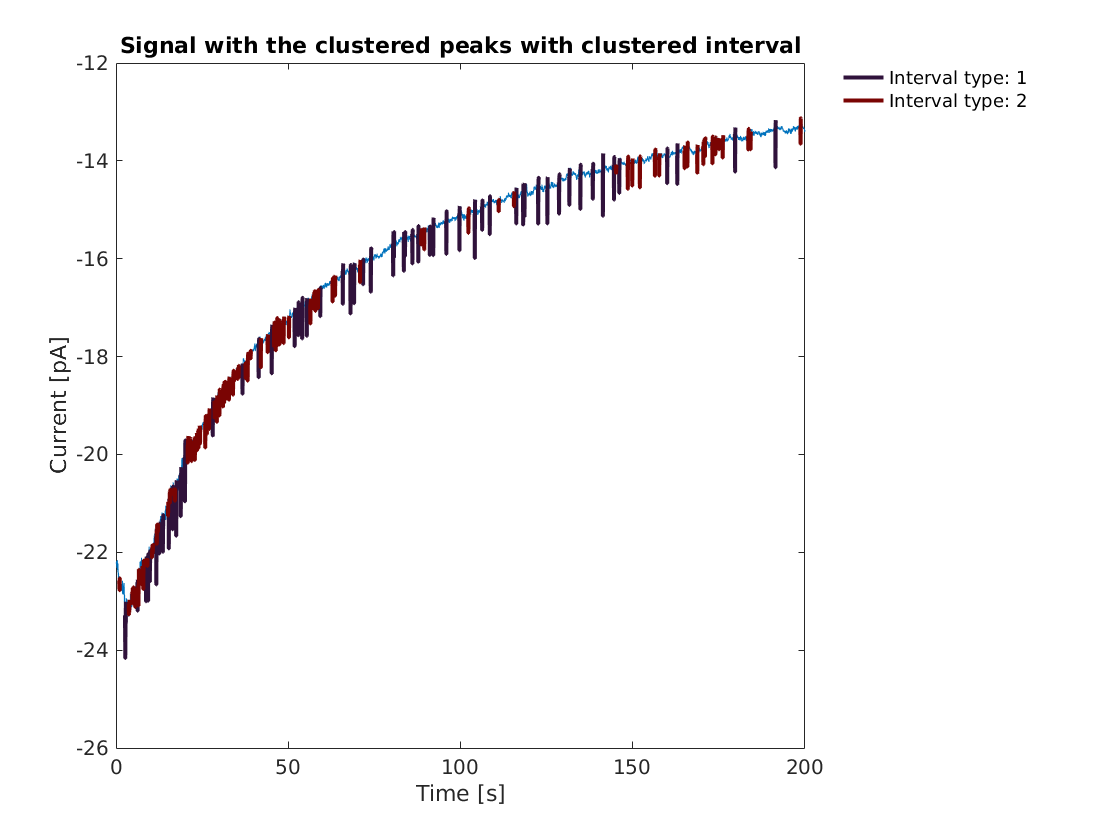

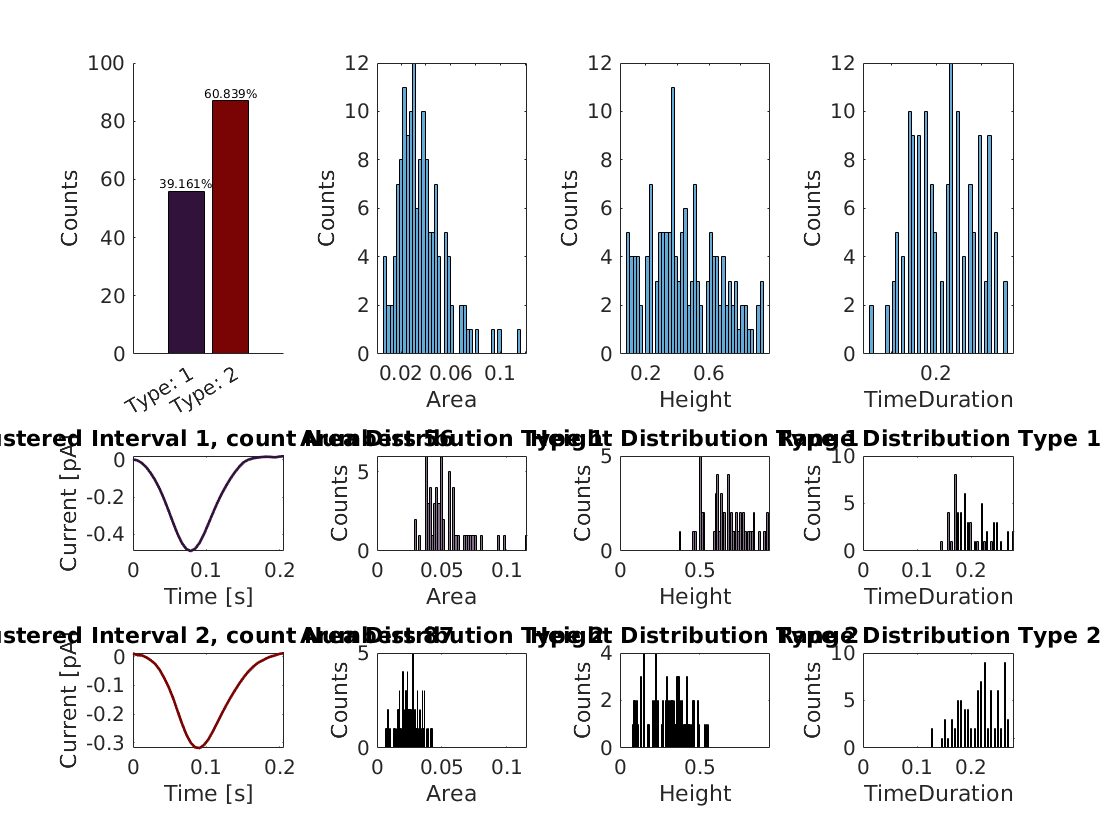

Sig2 = Sig2.KmeansGeAMSigTem(2,"Y","Y");

## Rematching Effect

it will replace the regulated raw templates by the new templates Sig1 = Sig1.Rematching(6,"Y","Y");

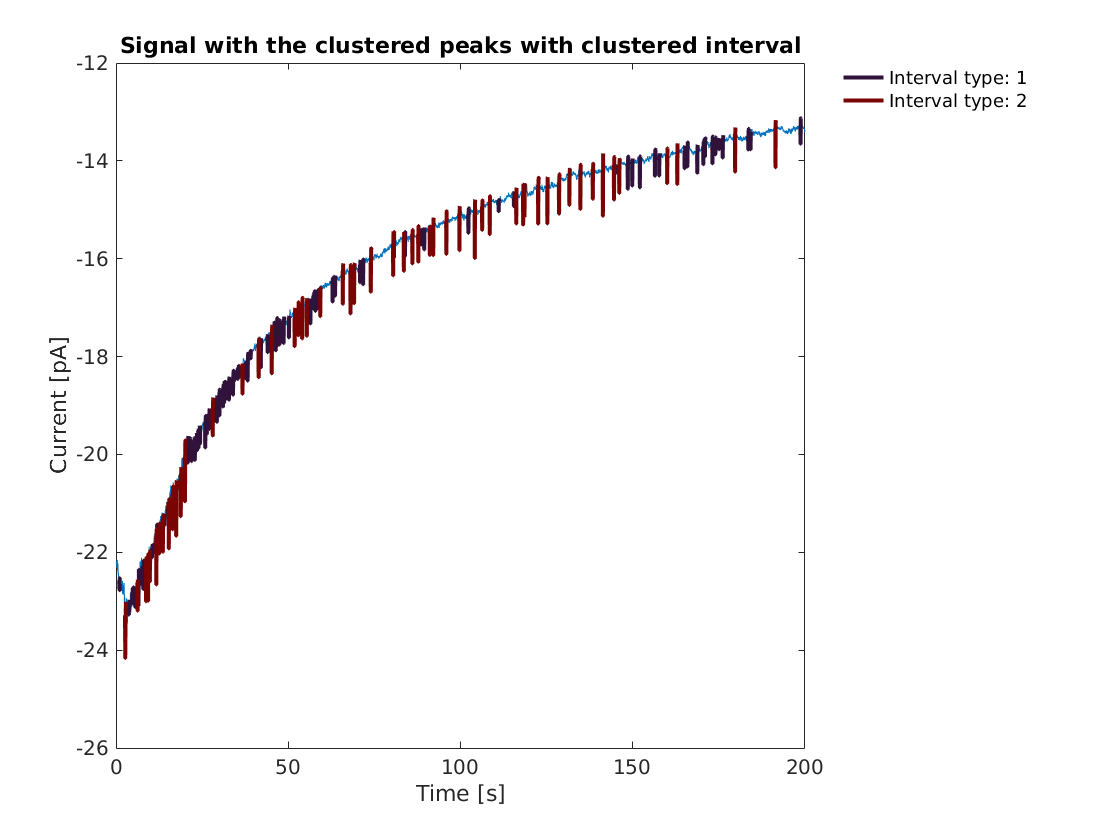

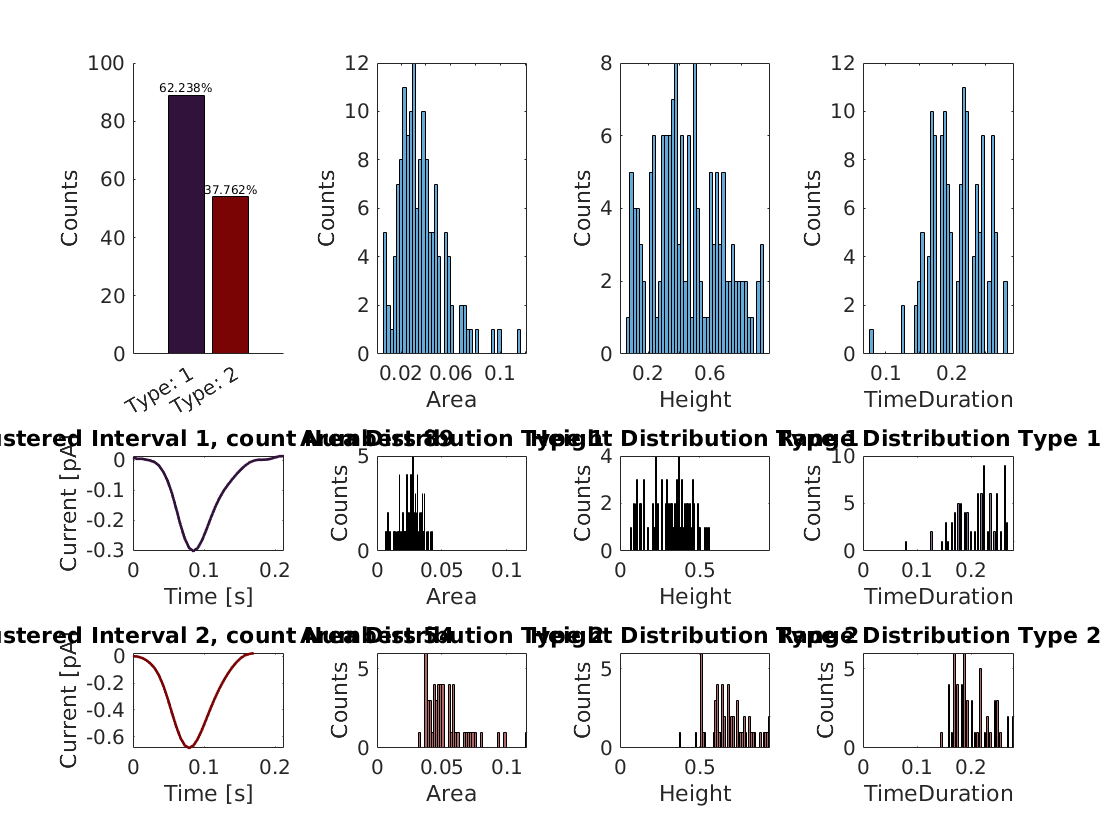

Sig3 = Sig2.KmeansGeAMSigTem(2,"N","N");
Sig3 = Sig3.Rematching(5,"Y","Y");